# **Signal and System CA2**

### **Part 3.**

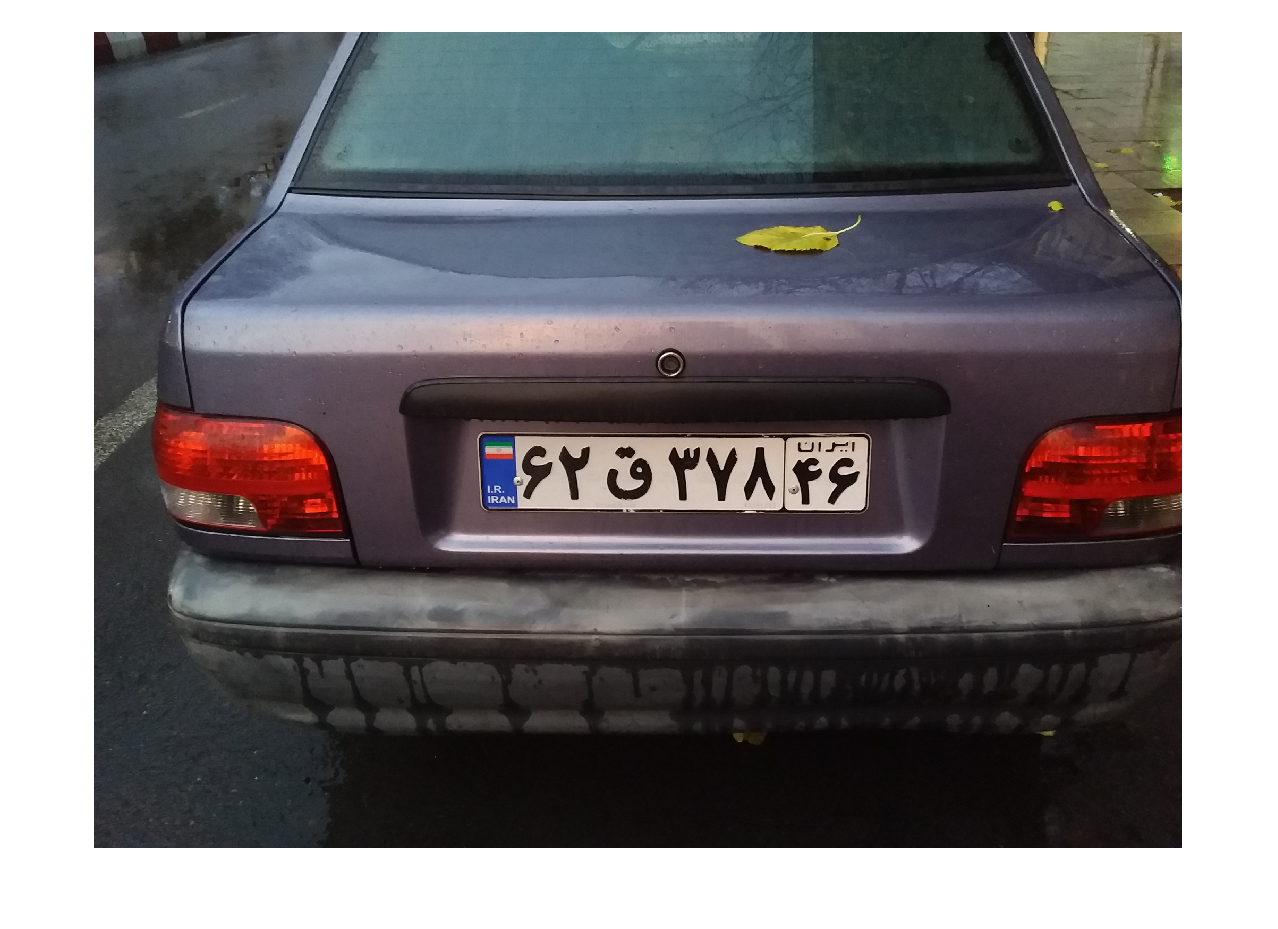

[file, path] = uigetfile('*.jpg;*.png;*.jpeg;*.bmp');
picture = imread([path, file]);
imshow(picture);

- Resize the picture and make it gray for better processing.

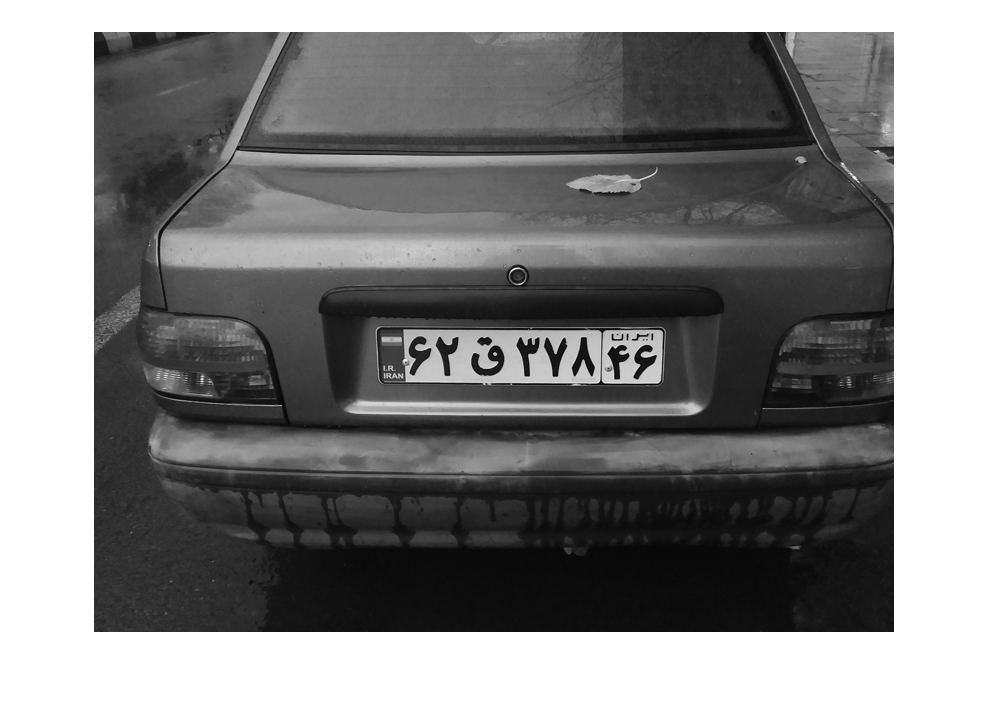

picWidth = 600;
picLength = 800;
picture = imresize(picture, [picWidth, picLength]);
picture = rgb2gray(picture);
imshow(picture);

- Then binarize this picture using `graythresh` for threshold.

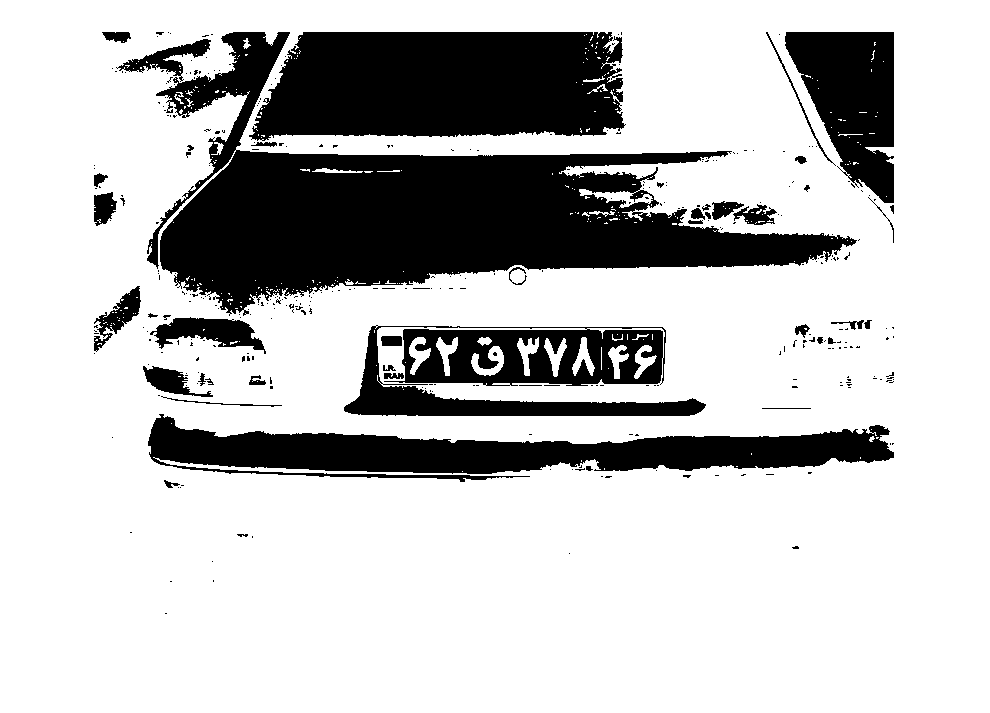

threshold = graythresh(picture);
picture = ~imbinarize(picture, threshold);
imshow(picture);

- Then we remove noises and background using the same technics in first part.

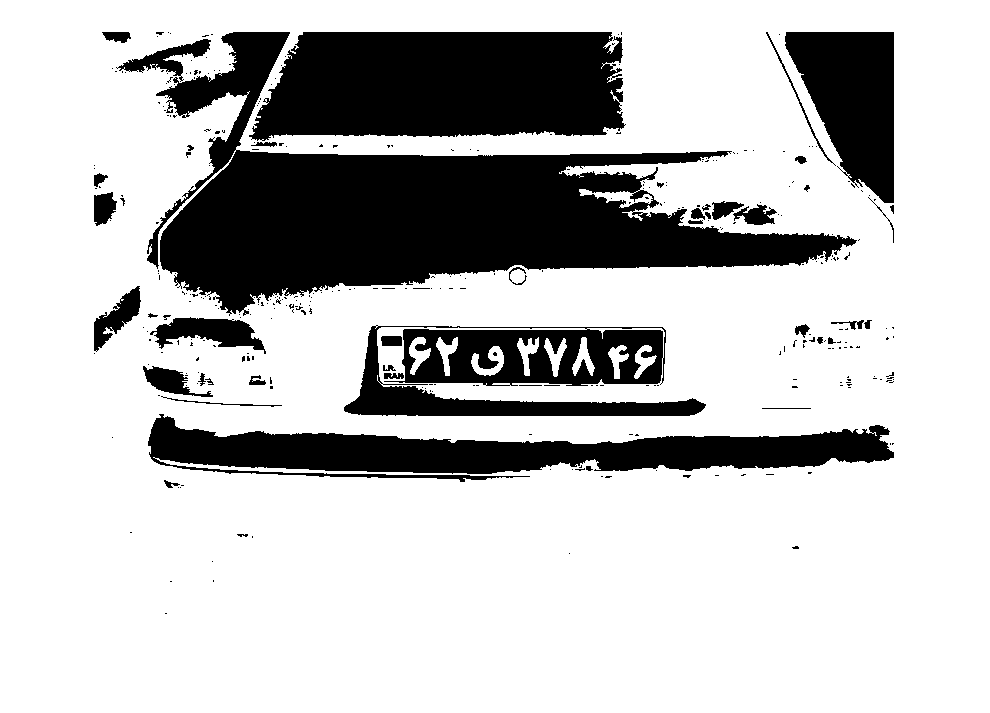

picture = myRemoveComFunc(picture, 280); 
imshow(picture);

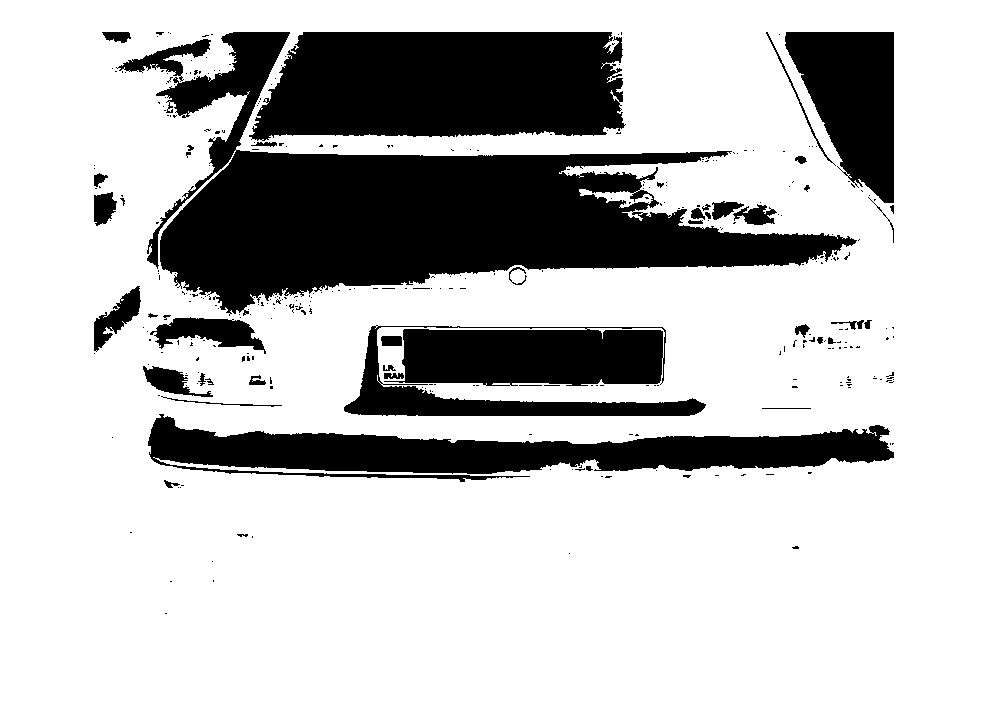

background = myRemoveComFunc(picture, 1250);
imshow(background);

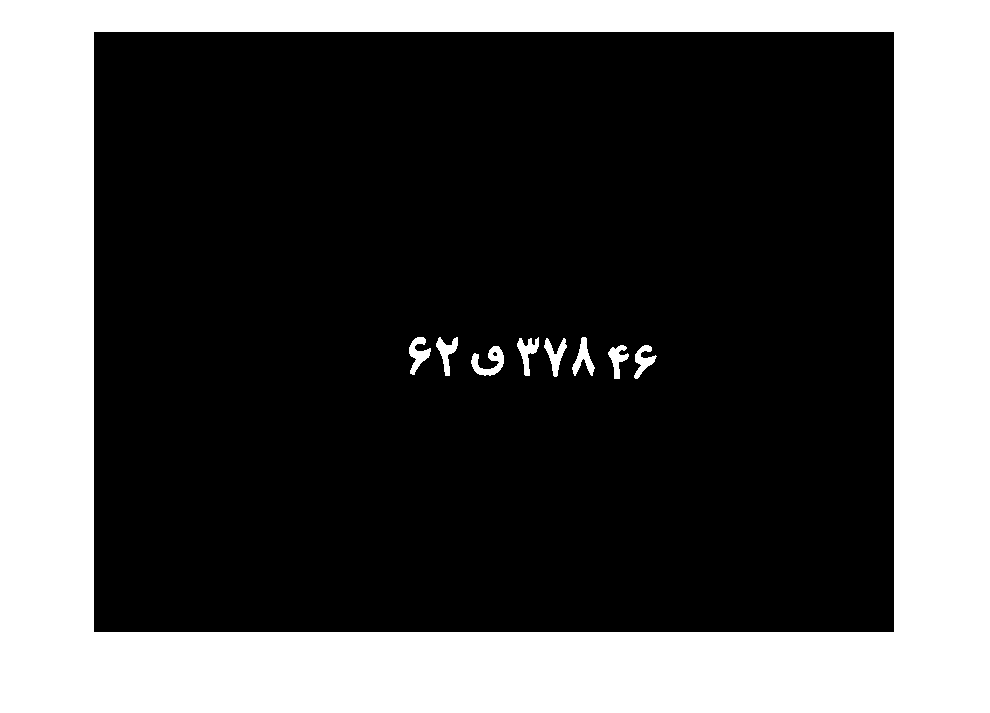

picture = picture - background;
imshow(picture);

- Now we have to detect the characters in the big picture. Since the original picture has many details, it is common that the picture we have in this part still contains some components that are not plate's characters. To overcome this problem, we first find the row with the most horizental edges in the picture. A horizental edge is where the next pixel (meaning the pixel that is not right side) is not same as the pixel we are at this time.

- For the detecting edges part, we iterate through rows and for each row we iterate through all columns and check for any edges in the pixels.

- Also for the found row to be considered as the answer, not every row with most changes count, but the rows that are in a limited position (which we estimated using some samples) are considered as answer. The reason for doing this is to reduce possible errors and to defend this values for estimation, we can say that in all pictures that are provided as samples which are veriaty of cars, it is obvoius that the plates are approximatly in the middle of the picture and also are not at the lowest position.(Roughly 45% to 80% of the width of the picture.) But of course this method can also produce errors for some samples.

MIN_ESTIMATED_ROW = picWidth / 2 - 100;
MAX_ESTIMATED_ROW = picWidth - 220;
MIN_ESTIMATED_COL = 150;
MAX_ESTIMATED_COL = picLength - 150;
[bottomRowFrame, topRowFrame] = deal(MAX_ESTIMATED_ROW, MIN_ESTIMATED_ROW);
[rightColFrame, leftColFrame] = deal(MAX_ESTIMATED_COL, MIN_ESTIMATED_COL);

limitedRowsEdges = zeros(1, MAX_ESTIMATED_ROW - MIN_ESTIMATED_ROW);

for i = MIN_ESTIMATED_ROW : MAX_ESTIMATED_ROW
    tmpMax = 0;
    for j = 1 : picLength - 1
        if picture(i, j) ~= picture(i, j + 1)
            tmpMax = tmpMax + 1;
        end
    end

    if i > MIN_ESTIMATED_ROW && i < MAX_ESTIMATED_ROW
        limitedRowsEdges(i - MIN_ESTIMATED_ROW) = tmpMax;
    end
end
[maxRowsEdges, rowWithMostEdges] = max(limitedRowsEdges);
rowWithMostEdges = rowWithMostEdges + MIN_ESTIMATED_ROW;

- For also columns, we use same estimation like the rows' process to make the processable area smaller.

limitedColsEdges = zeros(1, MAX_ESTIMATED_COL - MIN_ESTIMATED_COL);
for j = MIN_ESTIMATED_COL : MAX_ESTIMATED_COL
    tmpMax = 0;
    for i = 1 : picWidth - 1
        if picture(i, j) ~= picture(i + 1, j) 
            tmpMax = tmpMax + 1;
        end
    end
    

    if j > MIN_ESTIMATED_COL && j < MAX_ESTIMATED_COL
        limitedColsEdges(i - MIN_ESTIMATED_COL) = tmpMax;
    end
end
[maxColsEdges, colWithMostEdges] = max(limitedColsEdges);
colWithMostEdges = colWithMostEdges + MIN_ESTIMATED_COL;

- Now the last step for finding the area of the plate to make it ready of character recognizing, is to create the frame around it using rows and columns with maximum edges.

- For both top and bottom axis of the frame, we set a frame with maximum 30 pixels distance from the row with maximum edges. And also all rows inside that frame which at most have 30 less edges than the maximum number of edges are included.

for i = MIN_ESTIMATED_ROW + 1 : rowWithMostEdges
    if maxRowsEdges - limitedRowsEdges(i - MIN_ESTIMATED_ROW) < 30 && rowWithMostEdges - i < 30
        topRowFrame = i;
        break;
    end
end    

for i = size(limitedRowsEdges) :-1: rowWithMostEdges
    if maxRowsEdges - limitedRowsEdges(i) < 30 && i - rowWithMostEdges < 50
        bottomRowFrame = i;
        break;
    end
end


- We repeat the same process for columns with below numbers.

- ***Note that these numbers are just estimated using samples and surly are not accurate for every picture, but due to lack of time this esitmation is good for now.***

for j = MIN_ESTIMATED_COL + 1 : colWithMostEdges
    if maxColsEdges - limitedColsEdges(j - MIN_ESTIMATED_COL) < 40 && colWithMostEdges - j < 250
        leftColFrame = j;
        break;
    end
end

for j=size(limitedColsEdges) :-1: colWithMostEdges
    if maxColsEdges - limitedColsEdges(j) < 40 && j - colWithMostEdges < 250
        rightColFrame = j;
        break;
    end
end

- If the calculated height of plate is somehow small, we make a default height. This number is again estimated.

if bottomRowFrame - topRowFrame < 60
    bottomRowFrame = topRowFrame + 80;
end
% bottomRowFrame = (bottomRowFrame - topRowFrame < 60) ? topRowFrame + 80 : bottomRowFrame;

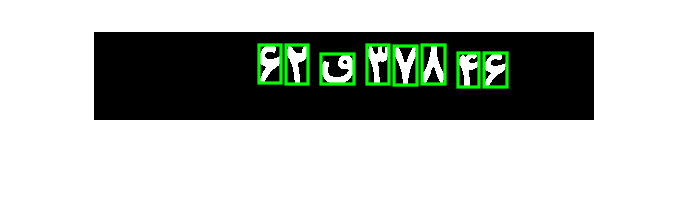

picture = picture(topRowFrame : bottomRowFrame, leftColFrame : rightColFrame);
imshow(picture);

[labeledComponents, numOfComps] = bwlabel(picture);
propied = regionprops(labeledComponents,'BoundingBox');
for n = 1 : size(propied, 1)
    rectangle('Position', propied(n).BoundingBox, 'EdgeColor', 'g', 'LineWidth',2)
end

- Now we only need to load the dataset and calculate corrolation for each character. This process is same as the previous parts.

DATASET_FOLDER = 'Persian Map Set';
contents = {dir(DATASET_FOLDER).name};
files = contents(3:end);

characters = cell(2, length(files));

for i = 1:length(files)
    c2m = cell2mat(files(i));
    characters(1, i) = {imread([DATASET_FOLDER, '\', c2m])};
    characters(2, i) = {c2m(1:find(c2m == '.') - 1)};
end
save("PersianCharacters.mat", 'characters');
final_output=[];
t = [];
for n = 1 : numOfComps
    [r, c] = find(labeledComponents == n);
    Y = picture(min(r):max(r), min(c):max(c));
    Y = imresize(Y, [100,80]);
    ro = zeros(1,size(characters, 2));
    for k = 1 : size(characters, 2)   
        characters{1, k} = imresize(characters{1, k}, [100, 80]);
        ro(k) = corr2(characters{1,k},Y);
    end
    
    [MAXRO, pos] = max(ro);
    if MAXRO > .5
        out = cell2mat(characters(2, pos));       
        final_output = [final_output out];
    end
end
file = fopen('persian_plate_from_car.txt', 'wt');
fprintf(file,'%s\n',final_output);
fclose(file);
final_output

final_output = '۶۲ق۳۷۸۴۶'